- Написание кода для сплайна по 100 узлам. Вывод на график синуса и сплайна, максимального отклонения.

n = 10;
x_l = linspace(0,n,100);
y = sin(x_l);
t = 0:0.005:n;
flag = 1;

hold on
grid on;
plot(t,sin(t),'b')

max_otkl = 0;
max_x = 0;
result = cubicsplines(x_l,y);
for i = 1:(length(x_l)-1)
    cs = @(x) result(i,1).*(x-x_l(i)).^3 + result(i,2).*(x-x_l(i)).^2 + result(i,3).*(x-x_l(i)) + result(i,4);
    xf = linspace(x_l(i),x_l(i+1),50);
    plot(xf, cs(xf));
    w = waitforbuttonpress;
    if (max(abs(sin(xf)-cs(xf)))) > max_otkl
        tmp = sin(xf)-cs(xf);
        max_otkl = max(abs(tmp));
        max_x = xf(abs(tmp) == max_otkl);
        flag = 1;
        if (sin(xf)-cs(xf)) > 0
            flag  = 0;
        end        
    end
end
y_corr = sin(max_x);
max_otkl, max_x

max_otkl = 2.7277e-04

max_x = 9.9608

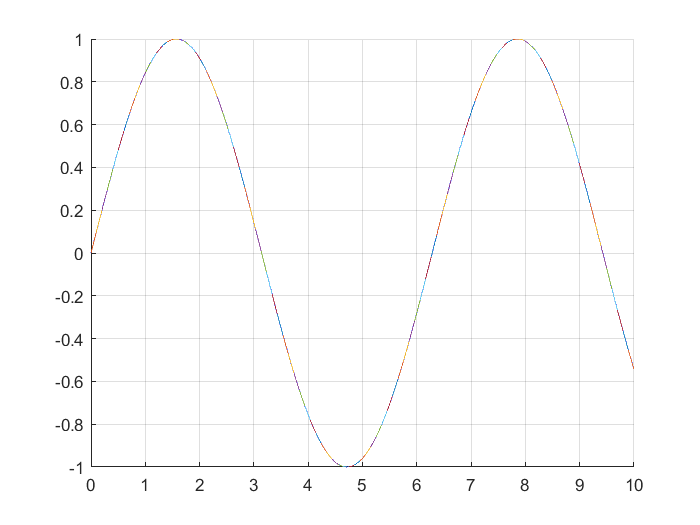

if (flag == 1)
    y_wr = y_corr+max_otkl;
else
    y_wr = y_corr-max_otkl;
end
line([max_x,max_x],[y_corr,y_wr],'color', 'black')

       2. Динамика изменения максимального отклонения в зависимости о количества узлов. Динамика изменения альф для сплайна.

hold off 

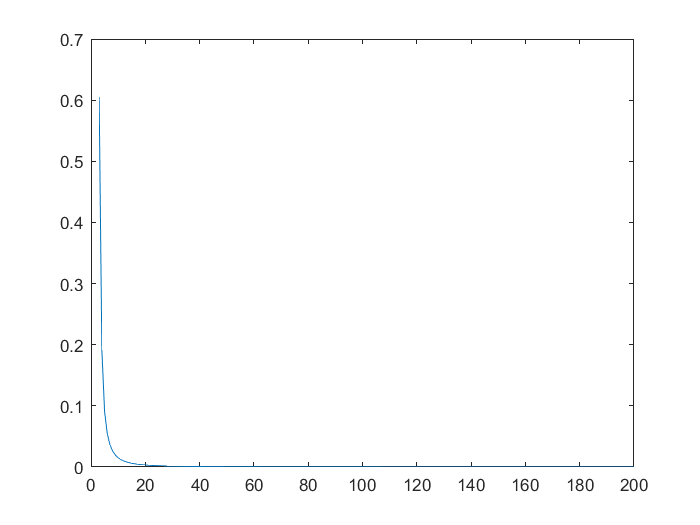

max_d = 200;
dynamic = zeros(max_d, 1);
alpha = zeros(max_d, 1);
for k = 3:1:max_d
    x_r = linspace(0, 5,k);
    y = sin(x_r);
    coefs = cubicsplines(x_r,y);
    for i = 1:(length(x_r)-1)
        cs = @(x) coefs(i,1).*(x-x_r(i)).^3 + coefs(i,2).*(x-x_r(i)).^2 + coefs(i,3).*(x-x_r(i)) + coefs(i,4);
        xf = linspace(x_r(i),x_r(i+1),30);
        if (max(abs(sin(xf)-cs(xf)))) > dynamic(k,1)
            tmp = abs(sin(xf)-cs(xf));
            dynamic(k,1) = max(tmp);
            alpha(k,1) = -log(dynamic(k,1))/log(k);
        end
    end
end
k = 3:1:max_d;
plot(k,dynamic(k));

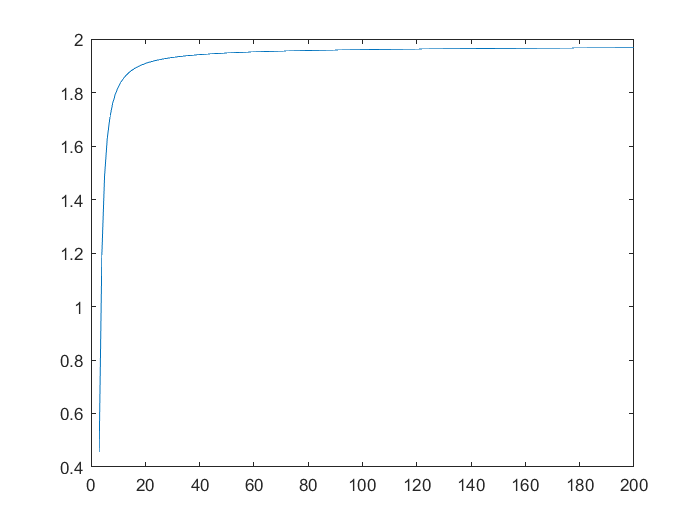

plot(k, alpha(k));